# Preprocess the data

close all;clear;clc;

## Analyze rat_010_07_04(well trained)

[M1, mPFC, ratios, eventTrain] = spikeTime2Train("data/rat_010_07_04.mat");
fprintf(['M1withSpike=%0.4f\nmPFCwithSpike=%0.4f\nM1multiSpike=%0.4f\n' ...
    'mPFCmultiSpike=%0.4f'], ratios)

M1withSpike=0.1314
mPFCwithSpike=0.0976
M1multiSpike=0.0499
mPFCmultiSpike=0.0402

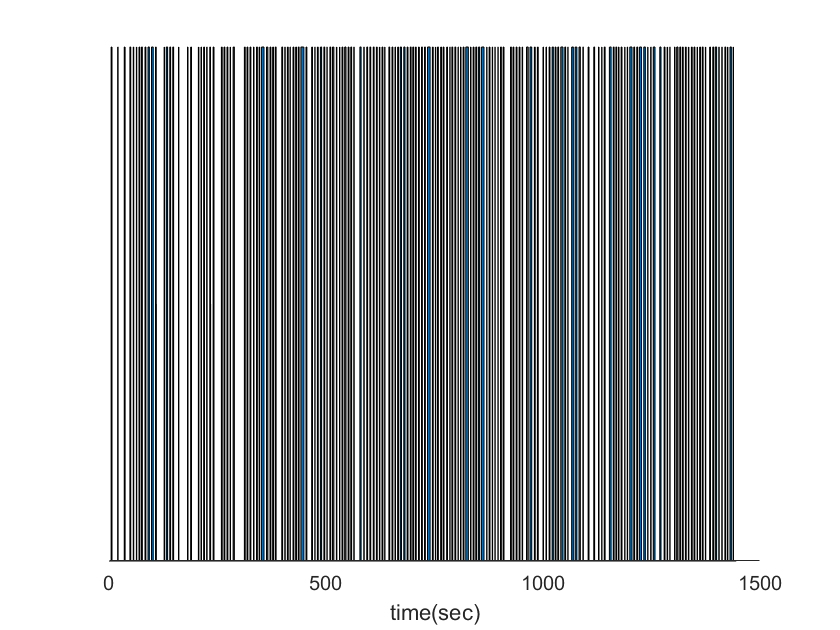

spikeLength = length(eventTrain);
figure
area(0.01:0.01:spikeLength*0.01, eventTrain)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")

event during 570.01s~910s seems continuously repeated. take for futher work.

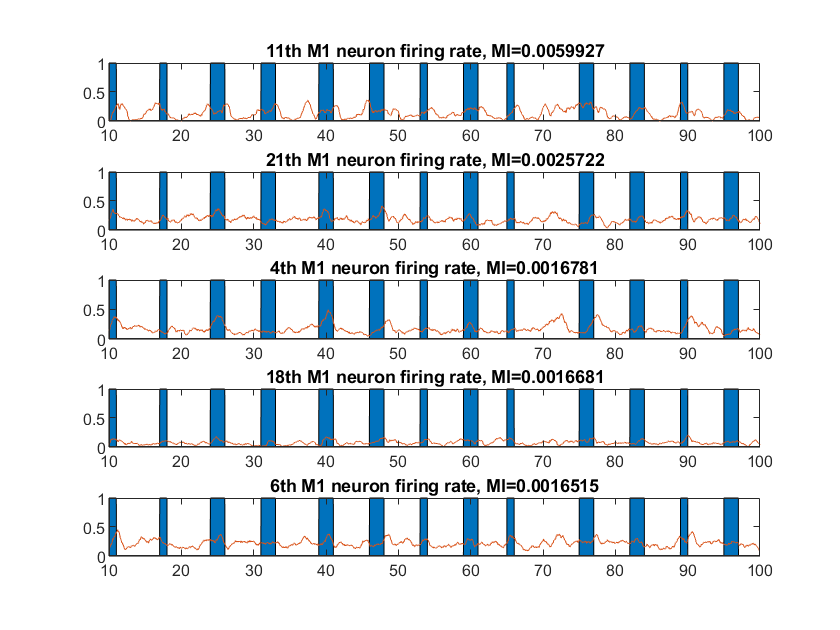

takenBins = 57001:91000;
spikeLength = length(takenBins);
eventTrain = eventTrain(takenBins)';
mPFC = mPFC(takenBins,:);
M1 = M1(takenBins,:);

emMI = mutualInformation(eventTrain, M1);
epMI = mutualInformation(eventTrain, mPFC);
nMI  = mutualInformation(M1, mPFC);

[mi, eM1index] = sort(emMI, 'descend');
t=10:0.01:100;
bins = 1000:10000;
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:5
  subplot(5,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(M1(bins, eM1index(i)), 50))
  hold off
  title([num2str(eM1index(i)), 'th M1 neuron firing rate, MI=', num2str(mi(i))])
end

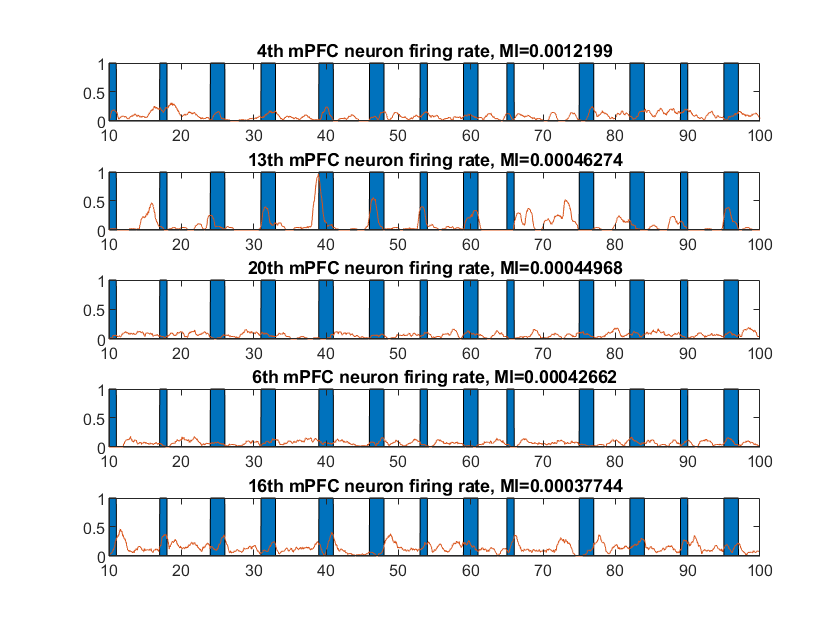

[mi, emPFCindex] = sort(epMI, 'descend');
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:5
  subplot(5,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, emPFCindex(i))*2, 50))
  hold off
  title([num2str(emPFCindex(i)), 'th mPFC neuron firing rate, MI=', num2str(mi(i))])
end

nMI(eM1index(1:5), emPFCindex(1:5))

ans = 	1.0e+-3 *

    0.0123    0.0185    0.1252    0.0972    0.1339
    0.0789    0.0077    0.0340    0.4346    0.1829
    0.1778    0.0213    0.0352    0.1078    0.2139
    0.1511    0.0331    0.0108    0.0019    0.0284
    0.0002    0.1227    0.0008    0.0481    0.0147


[mi, mPFCindex] = sort(nMI(eM1index(1:5),:), 2, 'descend');
disp(num2str(mPFCindex(:, 1:5)))

16   1  20  10  23
 6  17  10  16  14
17  16  14   4  12
 3   4  12  15   2
 1  13  23  22  11


mi(:, 1:5)

ans = 	1.0e+-3 *

    0.1339    0.1304    0.1252    0.1139    0.1117
    0.4346    0.2418    0.1958    0.1829    0.1328
    0.4347    0.2139    0.1932    0.1778    0.1648
    0.1587    0.1511    0.1356    0.1251    0.0607
    0.2527    0.1227    0.0820    0.0563    0.0556


## Mutual Information

Extract the best neurons

## For rat010_0615, M1 7/11/13 neurons, mPFC 5/6/7/8/13 neurons are selected

M1neurons   = [7 11 17];
mPFCneurons = [5 6 7 8 13];

ans =     11    21     4    18     6


ans =     0.0060    0.0026    0.0017    0.0017    0.0017


ans =      4    13    20     6    16


ans =     0.0012    0.0005    0.0004    0.0004    0.0004


ans = 	1.0e+-3 *

    0.0123    0.0185    0.1252    0.0972    0.1339
    0.0789    0.0077    0.0340    0.4346    0.1829
    0.1778    0.0213    0.0352    0.1078    0.2139
    0.1511    0.0331    0.0108    0.0019    0.0284
    0.0002    0.1227    0.0008    0.0481    0.0147


ans =     16     1    20    10    23
     6    17    10    16    14
    17    16    14     4    12
     3     4    12    15     2
     1    13    23    22    11


ans = 	1.0e+-3 *

    0.1339    0.1304    0.1252    0.1139    0.1117
    0.4346    0.2418    0.1958    0.1829    0.1328
    0.4347    0.2139    0.1932    0.1778    0.1648
    0.1587    0.1511    0.1356    0.1251    0.0607
    0.2527    0.1227    0.0820    0.0563    0.0556


M1spike = M1(:, M1neurons);
mPFCspike = mPFC(:, mPFCneurons);
% save("data/data_rat010_0615_spike_train_selected.mat", "M1spike", "mPFCspike")

Show results

figure(1)
t=50:0.01:80;
for i=1:length(M1neurons)
    subplot(length(M1neurons)+length(mPFCneurons), 1, i)
    area(t, M1spike(5000:8000, i))
    title(['M1 ', num2str(M1neurons(i)), 'th neuron'])
    set(gca, 'TickLength', [0 0])
    set(gca, 'ytick', [])
    set(gca, 'box', 'off')
end
for i=1:length(mPFCneurons)
    subplot(length(M1neurons)+length(mPFCneurons), 1, i+length(M1neurons))
    area(t, mPFCspike(5000:8000, i))
    title(strcat("mPFC ", num2str(mPFCneurons(i)), "th neuron"))
    set(gca, 'TickLength', [0 0])
    set(gca, 'ytick', [])
    set(gca, 'box', 'off')
end
xlabel("time(sec)")

show smoothed firing rate

figure(2)
t=1000:0.01:1500;
for i=1:length(M1neurons)
    firingRate = gaussianSmooth(M1spike(100000:150000,i), 50);
    subplot(length(M1neurons)+length(mPFCneurons), 1, i)
    title(['M1 ', num2str(M1neurons(i)), 'th neuron'])
    plot(t, firingRate)
end
for i=1:length(mPFCneurons)
    firingRate = gaussianSmooth(mPFCspike(100000:150000,i), 50);
    subplot(length(M1neurons)+length(mPFCneurons), 1, i+length(M1neurons))
    title(strcat("mPFC ", num2str(mPFCneurons(i)), "th neuron"))
    plot(t, firingRate)
end
xlabel("time(sec)")

## EVT series

eventLength = floor(Stop/timebins);
allEvent = zeros(1, eventLength);
% spikeTrain = double(accumarray(fix(eval(channelName)*1/timebins)+1, 1)>threshold);


